# 时域实验

## 一、数据获取

读取实验所测得数据这里使用pitch数据

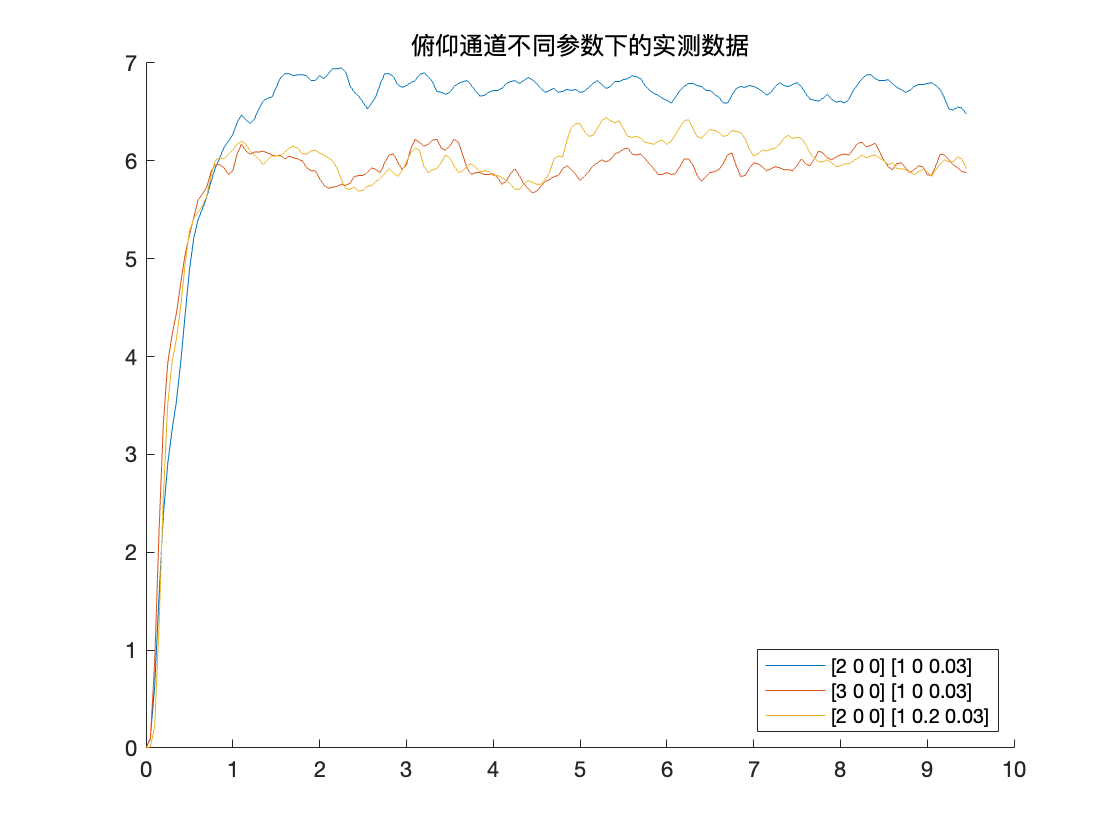

sheets=sheetnames("TimeDomain.xlsx");
data=readmatrix("TimeDomain.xlsx","Sheet",sheets(1));
cont=readmatrix("TimeDomain.xlsx","Sheet","pitchparam");
figure();hold on;
for i=1:3
    label=sprintf("[%s] [%s]",join(string(cont(i,2:4))),join(string(cont(i,5:7))));
    plot(data(:,2*i-1),data(:,2*i),'DisplayName',label)
end
title("俯仰通道不同参数下的实测数据")
legend('Location',"southeast")

## 二、系统辨识

进行系统辨识获得整个控制系统闭环传递函数，并反推出飞行器该通道的传递函数

i=1;
t=data(:,2*i-1);
y=data(:,2*i);
c=cont(i,2:7);
A=cont(i,1);
Co=pid(c(1),c(2),c(3));
Ci=pid(c(4),c(5),c(6));
nt=4;
N=length(y)-nt;
u=A*[zeros(nt,1);ones(N,1)];
idData=iddata(y,u,0.05);%注意这里的0.05为T sample time 应该与diff(t)一致
Pid=tfest(idData,3,0)

Pid =
 
  From input "u1" to output "y1":
                163
  --------------------------------
  s^3 + 24.1 s^2 + 93.19 s + 120.9
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 0
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "idData".
Fit to estimation data: 91.41%                     
FPE: 0.009279, MSE: 0.00862                        


## 三、阶跃响应及性能指标

绘制辨识出来的传递函数阶跃响应与实际响应的关系

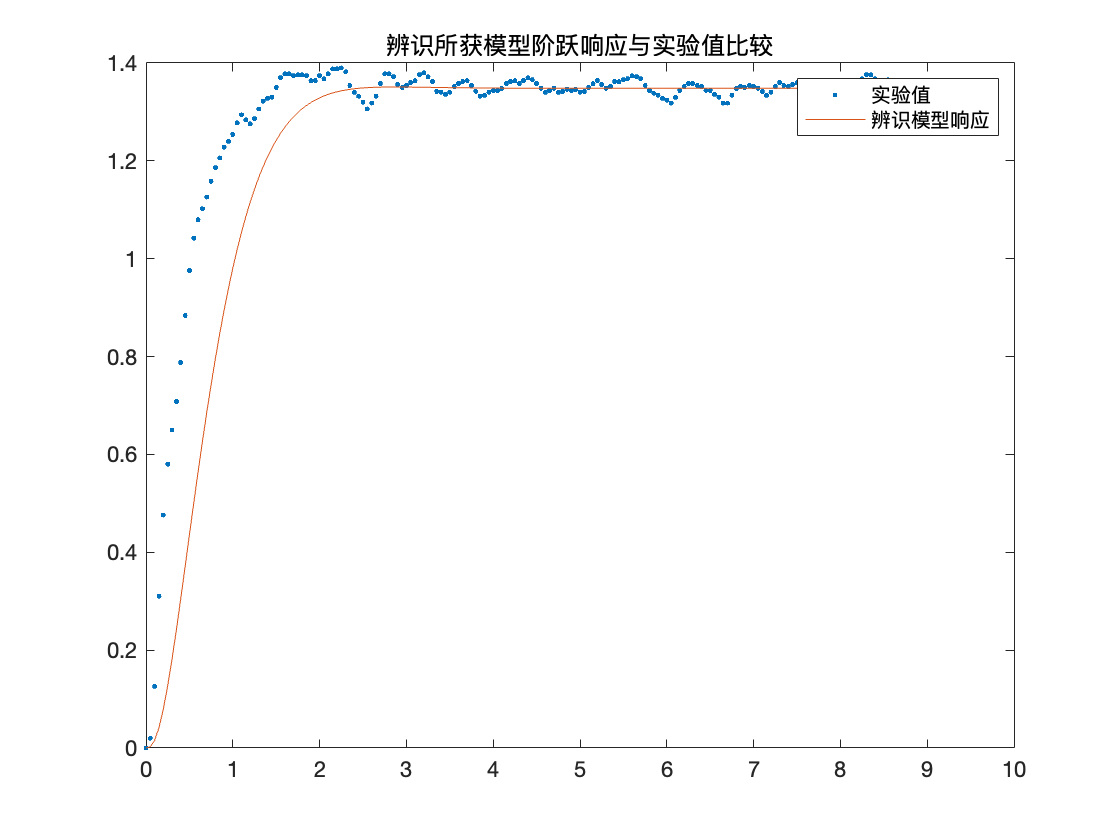

figure();
[yid,tid]=step(Pid,t);
plot(t,y/5,'.',tid,yid);
legend('实验值','辨识模型响应');
title('辨识所获模型阶跃响应与实验值比较');

info=stepinfo(Pid)

info = 包含以下字段的 struct :
        RiseTime: 1.1569
    SettlingTime: 1.9186
     SettlingMin: 1.2141
     SettlingMax: 1.3509
       Overshoot: 0.1977
      Undershoot: 0
            Peak: 1.3509
        PeakTime: 2.8731
